%addpath 'iwave\development\matlab'

load_parameters

t_end = 0.05; % secs
t = 0 : t_step : t_end;

%% generate signal and noise
f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_a, axion_linewidth);
signal = generate_axion_signal(t, f_sampling, f_axion, axion_power);
noise_power = calculate_noise_power(f_sampling, T);
noise = generate_thermal_noise(t, f_sampling, noise_power);

band_width = 1000;
f_0 = f_a;
band = [f_0-band_width/2, f_0+band_width/2]

band = 1.0e+07 *

    2.4177    2.4178


Q_resonator = f_0 / band_width

Q_resonator = 2.4178e+04

%displayband = [f_0 - 20*axion_linewidth, f_0 + 20*axion_linewidth]

SNR_before = bandpower(signal)/bandpower(noise)

SNR_before = 9.4650e-05

signal_qred = do_q_reducing_factor(signal, f_axion, f_0, Q_resonator);
SNR_before_qred = bandpower(signal)/bandpower(noise)

SNR_before_qred = 9.4650e-05

iwave_input_f = prepare_iwave_input(signal + noise, f_0, band_width, f_sampling);
iwave_input_f_qred = prepare_iwave_input(signal_qred + noise, f_0, band_width, f_sampling);

power_in_band = bandpower(iwave_input_f, f_sampling, band);
power =         bandpower(iwave_input_f, f_sampling, [0, f_sampling/2.001]);
fraction_of_power_in_band_after = power_in_band / power;

%% run iwave
tau_iwave = 1e-5; % before adding noise
tau_iwave = 3e-4;
tau_iwave = 3e-4; % for 1* mult
%tau_iwave = 1e-4
%tau_iwave = 30e-4
%tau_iwave = 15e-4
%tau_iwave = 3.8e-4/0.1;
%tau_iwave = 20e-4; % for 10* mult

% front to chop off
% start_secs = 4 * tau_iwave;
start_secs = 0.0025;
assert(start_secs < t(end)/3)
start = round(start_secs * f_sampling);

[f_iwave, amp] = run_iwave(iwave_input_f, f_sampling, f_0, tau_iwave);
[f_iwave_qred, amp] = run_iwave(iwave_input_f_qred, f_sampling, f_0, tau_iwave);

% don't need to plot every single point
div = 1000;

slice = (1:div:length(t));
t_small       = t(slice);
f_axion_small = f_axion(slice);
f_iwave_small = f_iwave(slice);
f_iwave_small_qred = f_iwave_qred(slice);
amp_small = amp(slice);

start = round(start / div)

start = 625

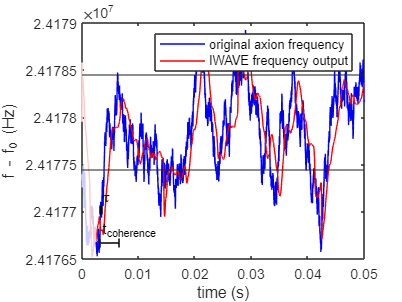

% plot iwave before and after
figure
%adstyle(8, 8);

plot(t_small(start:end), f_axion_small(start:end)-0, 'Color', [0,0,1], 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small(1:start),   f_axion_small(1:start)  -0, 'Color', [0.8,0.8,1], 'HandleVisibility','off')
plot(t_small(start:end), f_iwave_small(start:end)-0, 'Color', [1,0,0], 'DisplayName','IWAVE frequency output')
plot(t_small(1:start),   f_iwave_small(1:start)  -0, 'Color', [1,0.8,0.8], 'HandleVisibility','off')
ylim(y_lim)
x_lim = xlim();
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

y_width = y_lim(2) - y_lim(1);
x_width = x_lim(2) - x_lim(1);

x_start = x_lim(1) + x_width/15;
y_1 = y_lim(1) + y_width/15;
y_2 = y_1 + y_width/7;

plot([x_start, x_start + t_coherence], [y_1, y_1], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
plot([x_start, x_start + tau_iwave], [y_2, y_2], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')

text(x_start, y_1 + y_width/20, 't_{coherence}')
text(x_start, y_2 + y_width/20, '\tau')

yline(band, 'HandleVisibility','off')

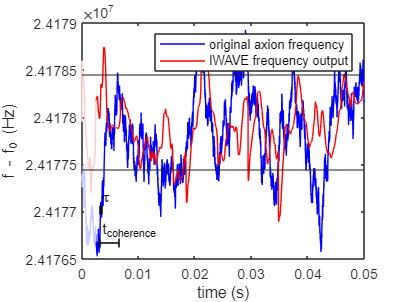

% plot iwave before and after
figure
%adstyle(8, 8);

plot(t_small(start:end), f_axion_small(start:end)-0, 'Color', [0,0,1], 'DisplayName','original axion frequency')
y_lim = ylim();
hold on
plot(t_small(1:start),   f_axion_small(1:start)  -0, 'Color', [0.8,0.8,1], 'HandleVisibility','off')
plot(t_small(start:end), f_iwave_small_qred(start:end)-0, 'Color', [1,0,0], 'DisplayName','IWAVE frequency output')
plot(t_small(1:start),   f_iwave_small_qred(1:start)  -0, 'Color', [1,0.8,0.8], 'HandleVisibility','off')
ylim(y_lim)
x_lim = xlim();
legend()
xlabel('time (s)')
ylabel('f - f_0 (Hz)')

y_width = y_lim(2) - y_lim(1);
x_width = x_lim(2) - x_lim(1);

x_start = x_lim(1) + x_width/15;
y_1 = y_lim(1) + y_width/15;
y_2 = y_1 + y_width/7;

plot([x_start, x_start + t_coherence], [y_1, y_1], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')
plot([x_start, x_start + tau_iwave], [y_2, y_2], '-|', 'Color','black', 'LineWidth',1, 'HandleVisibility','off')

text(x_start, y_1 + y_width/20, 't_{coherence}')
text(x_start, y_2 + y_width/20, '\tau')

yline(band, 'HandleVisibility','off')

%saveas(gca, 'figures/chop.eps', 'epsc');

% now remove the start as it can go a bit off
% start_samples = start_secs * f_sampling;
% t       = t      (start_samples:end);
% f_iwave = f_iwave(start_samples:end);
% f_axion = f_axion(start_samples:end);
% signal  = signal (start_samples:end);
% noise   = noise  (start_samples:end);

% find avg diff between iwave and original
% avg_dist_dynamic = rms(f_iwave - f_axion);
% Qmax_dynamic = 2 * f_0 / avg_dist_dynamic;
% 
% avg_dist_static = rms(f_0 * ones(size(t)) - f_axion);
% Qmax_static = 2 * f_0 / avg_dist_static;